Temps = readtable('Temperaturas.txt');
Temps = table2array(Temps);

Punto 1

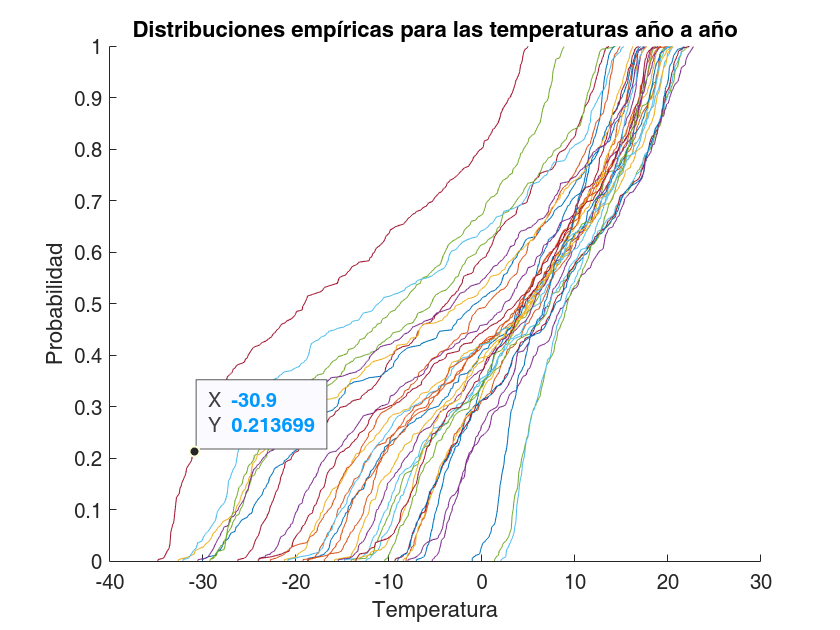

%Distribución empírica
A = zeros(35,1);
hold on
title("Distribuciones empíricas para las temperaturas año a año")
xlabel("Temperatura")
ylabel("Probabilidad")
for i = 1:35
    temp = Temps(:,i);
    [F,t] = ecdf(temp);
    tq1 = t(find(t>=0)); tq2 = t(find(t<0));
    Fq1 = F(find(t>=0)); Fq2 = F(find(t<0));
    A(i) = trapz(tq1,1-Fq1) - trapz(tq2,Fq2);
    plot(t,F)
end

%Tabla de doble entrada con la media

means = mean(Temps,1);

doubletable = zeros(36,36);

doubletable(1,2:36) = means;

doubletable(2:36,1) = means;

for i = 2:36
    for j = 2:36
        valori = means(i-1);
        valorj = means(j-1);
        doubletable(i,j) = i-1;
        if valorj > valori
            doubletable(i,j) = j-1;
        end
       
        if i == j
            doubletable(i,j) = 0; 
        end

         

    end
end

array2table(doubletable)

ans = 36×36 table
    doubletable1    doubletable2    doubletable3    doubletable4    doubletable5    doubletable6    doubletable7    doubletable8    doubletable9    doubletable10    doubletable11    doubletable12    doubletable13    doubletable14    doubletable15    doubletable16    doubletable17    doubletable18    doubletable19    doubletable20    doubletable21    doubletable22    doubletable23    doubletable24    doubletable25    doubletable26    doubletable27    doubletable28    doubletable29    <

ans = 0.5193

ans = 0.5193

%Tabla de doble entrada con la estimación empírica de la media
means = A'

means =    11.6286   14.1814   13.8433   12.0464   15.5641   17.5864   21.0584   21.7164   21.3612   19.8023   19.4401   20.0478   20.4314   16.4929   16.2411   19.2790   23.5851   23.7625   22.0258   23.4555   24.6000   26.4963   20.8197   17.6123   16.5756    8.5010    7.4666   17.2632    7.9467   21.7653   27.7195   25.3837   19.4678   22.7664   18.1982


doubletable = zeros(36,36);

doubletable(1,2:36) = means;

doubletable(2:36,1) = means;

for i = 2:36
    for j = 2:36
        valori = means(i-1);
        valorj = means(j-1);
        doubletable(i,j) = i-1;
        if valorj > valori
            doubletable(i,j) = j-1;
        end
       
        if i == j
            doubletable(i,j) = 0; 
        end

         

    end
end

array2table(doubletable)

ans = 36×36 table
    doubletable1    doubletable2    doubletable3    doubletable4    doubletable5    doubletable6    doubletable7    doubletable8    doubletable9    doubletable10    doubletable11    doubletable12    doubletable13    doubletable14    doubletable15    doubletable16    doubletable17    doubletable18    doubletable19    doubletable20    doubletable21    doubletable22    doubletable23    doubletable24    doubletable25    doubletable26    doubletable27    doubletable28    doubletable29    <

Punto 2

temp = Temps(:,1);
[F,t] = ecdf(temp);
tq1 = t(find(t>=0)); tq2 = t(find(t<0));
Fq1 = F(find(t>=0)); Fq2 = F(find(t<0));
estimator = trapz(tq1,1-Fq1) - trapz(tq2,Fq2)

estimator = 4.6625

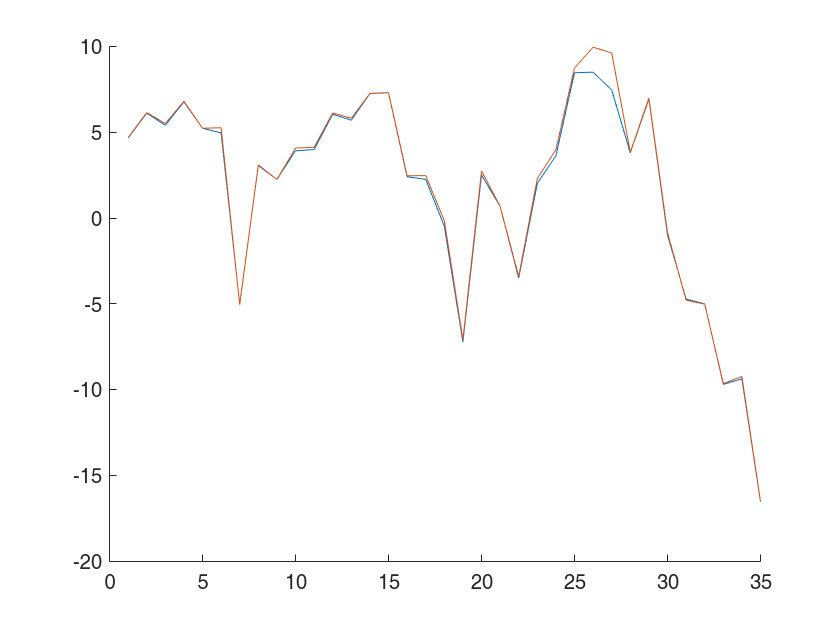

clf
hold on
plot(1:35,A)
plot(1:35, mean(Temps,1))

Punto 3

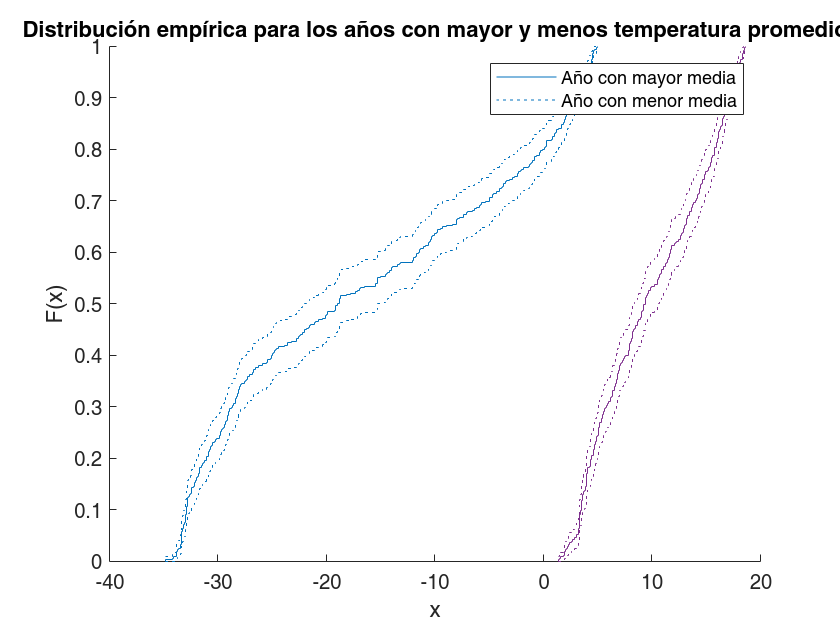

[minimum, minindex] = min(means);
[maximum, maxindex] = max(means);

clf
hold on
title("Distribución empírica para los años con mayor y menos temperatura " + ...
    "promedio")
xlabel("Temperatura")
ylabel("Probabilidad")
ecdf(Temps(:,minindex),'Bounds','on');
ecdf(Temps(:,maxindex),'Bounds','on');
legend({'Año con mayor media','Año con menor media'})

Punto 4

n = 100

n = 100

X = wblrnd(5, 0.8,n,1);
[F,t] = ecdf(X);
WeibulF = wblcdf(t,5,0.8);
min(abs(WeibulF-F))

ans = 3.8950e-05

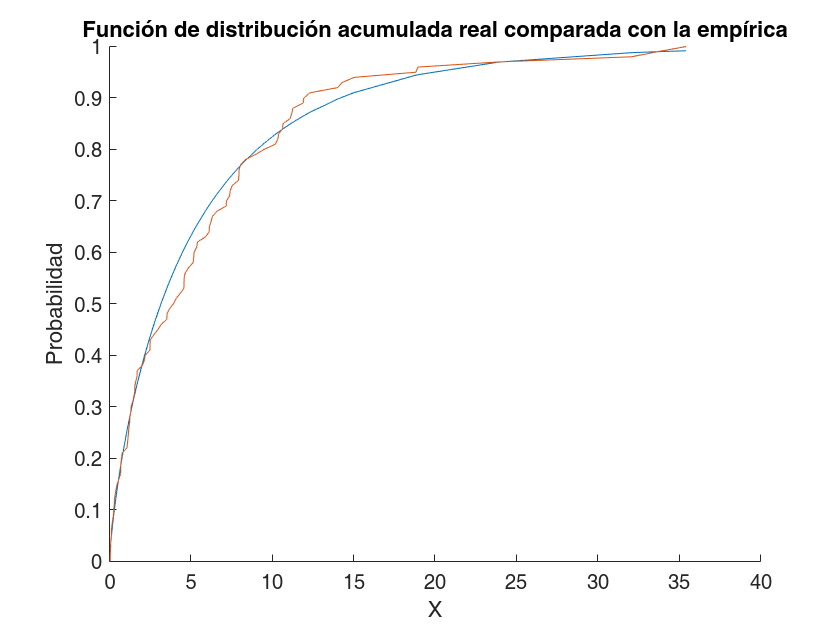

clf
hold on
plot(t,WeibulF)
plot(t,F)
title("Función de distribución acumulada real comparada con la empírica")
xlabel("X")
ylabel("Probabilidad")

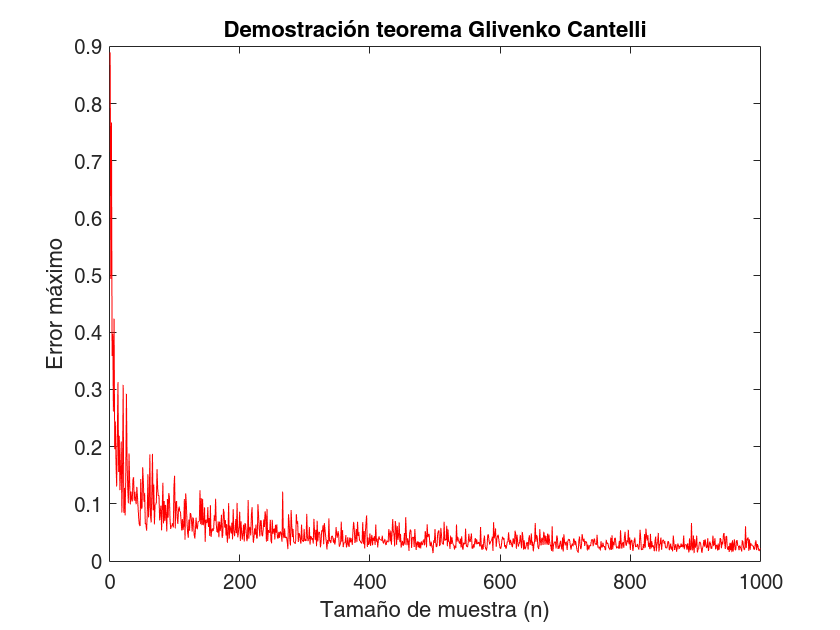

maxs = zeros(991,1);
for i = 1:1000
    X = wblrnd(5, 0.8,i,1);
    [F,t] = ecdf(X);
    WeibulF = wblcdf(t,5,0.8);
    maxs(i) = max(abs(WeibulF-F));
end
clf
plot(maxs,'r')
title("Demostración teorema Glivenko Cantelli")
xlabel("Tamaño de muestra (n)")
ylabel("Error máximo")

Punto 7

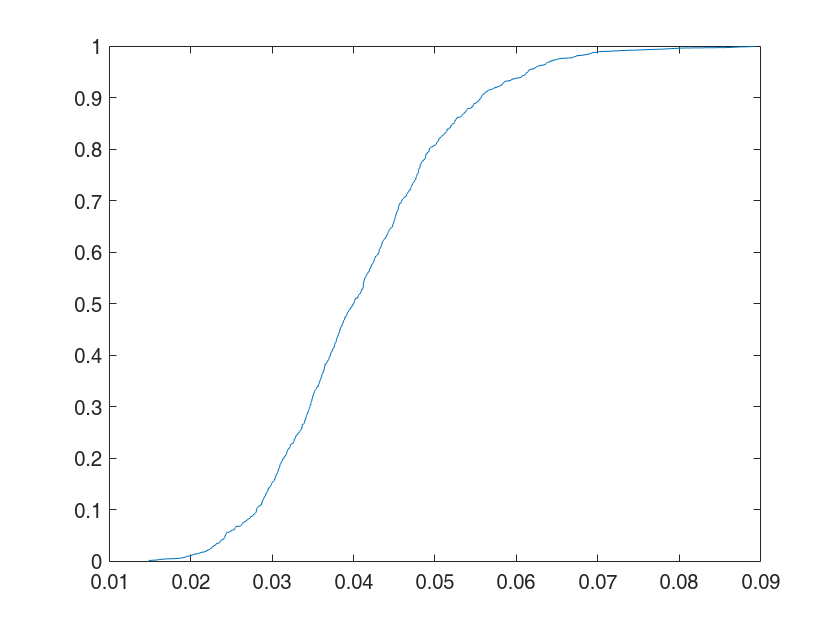

clf
weibul = wblrnd(5, 0.8,1000,1000);
weibulSort = sort(weibul,1);
ithValue = weibulSort(5,:);
[F,t] = ecdf(ithValue);
plot(t,F)

clear all
syms i
n=1000;
j = 21;
t = 0.03;
x = double(symsum(nchoosek(n,i)*(wblcdf(t)^(i)*(1-wblcdf(t))^(n-i)),i,21,1000)) 

x = 0.9605

n=1000;
j = 21;
t=0:0.01:0.9

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


x = n*nchoosek(n-1,j-1)*((wblcdf(t).^(j-1)).* ...
    ((1-wblcdf(t)).^(n-j)).*wblpdf(t));
ecdf(x)

(wblcdf(t).^(j-1)).* ...
    ((1-wblcdf(t)).^(n-j))

ans = 1.0e-42 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0004    0.0017    0.0051    0.0127    0.0269    0.0496    0.0812    0.1200    0.1623    0.2029    0.2367    0.2596    0.2694    0.2659    0.2508    0.2269    0.1977    0.1664    0.1356    0.1073    0.0826    0.0620    0.0454    0.0325    0.0228    0.0157    0.0106    0.0071    0.0046    0.0030    0.0019    0.0012    0.0007    0.0004    0.0003    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000
